# Implementation of Histogram Equilization

### Global Histogram Equiliztion

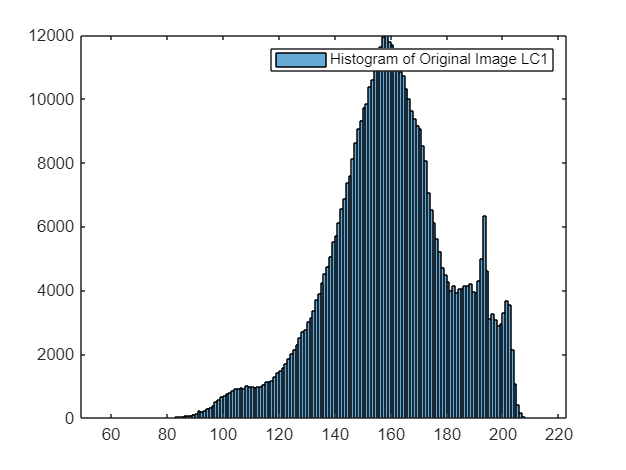

% im_1 = imread("LC1.png");
% im_2 = imread("E:\Academics\Semester-5\CS663-DIP\Assignments\Assignment-2\LC2.jpg");
[rnum2, cnum2] = size(im_2);
figure;
histogram(im_2(:));
legend("Histogram of Original Image LC1");

### Number of values in a Intensity bin calculator function

function [weights_list] = weights_calculator(image_matrix)
    weights_list = zeros([1,256]);
    [rnum, cnum] = size(image_matrix);
    for i = 1:rnum
        for j = 1:cnum
            intensity_value = image_matrix(i,j) + 1;
            weights_list(intensity_value) = weights_list(intensity_value)+1;
        end
    end

end

### CDF calculator function

function [transf_int_values] = int_trans(norm_hist)
    cdf_list = [norm_hist(1)];
    for i = 2:256
        cdf = norm_hist(i);
        cdf_list = [cdf_list, cdf+cdf_list(end)];
    end
    transf_int_values = round(cdf_list.*255);

end

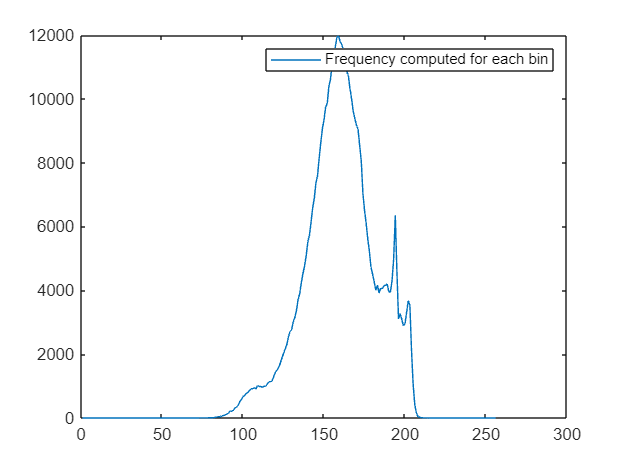

calc_hist = weights_calculator(im_2);
plot(calc_hist);
legend("Frequency computed for each bin");

### Performing Histogram Equilization

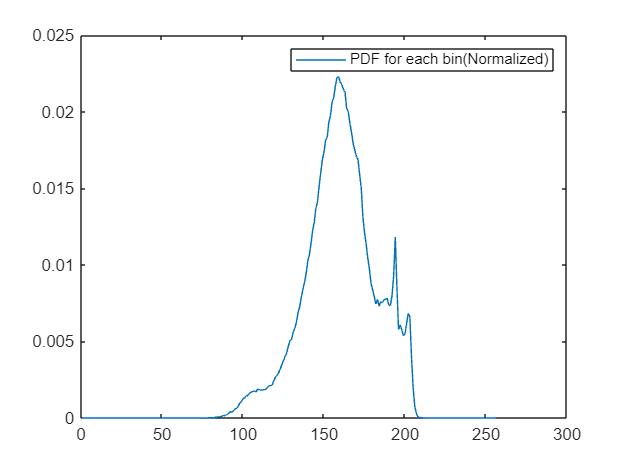

norm_cal_hist = calc_hist/(rnum2*cnum2);
plot(norm_cal_hist);
legend("PDF for each bin(Normalized)");

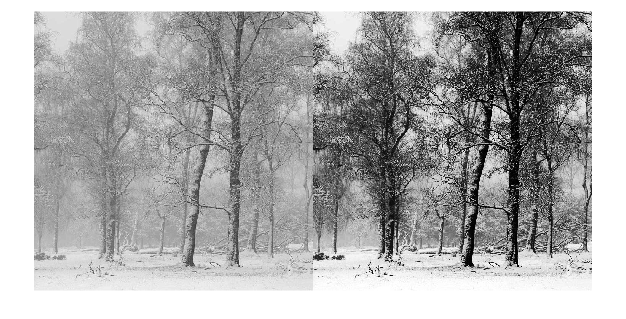

trans_inten_values = int_trans(norm_cal_hist);
trans_im2 = zeros(rnum2, cnum2);
for i =1:rnum2
    for j = 1:cnum2
        int_value = im_2(i, j) +1;
        trans_im2(i, j) = trans_inten_values(int_value);
    end
end
trans_im2 = uint8(trans_im2);
imshowpair(im_2, trans_im2, "montage");

imwrite(trans_im2, "LC2_transformed.jpg");